# ELABORATO IBRIDO

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo ibrido (MPI + OpenMP) per risolvere il prodotto vettoriale tra una matrice, di dimensioni M*N, e un vettore di reali, di dimensione N, su p processi e t thread valutando le diverse configurazioni di p e t.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permettere l'esecuzione del software in un ambiente parallelo.

## DESCRIZIONE DELL'ALGORITMO

In particolare le fasi dell'algoritmo, implementato nel file `elaborato_ibrido.c`, sono:

1) Distribuzione per righe della matrice in p processi e distribuzione del vettore: ognuno dei p processi eseguirà il prodotto vettoriale tra la porzione di matrice ricevuta dal processo *root (*cioè quello con rank 0), e tutto il vettore;

2) Elaborazione del prodotto vettoriale in parallelo in t thread su ogni processo mediante le direttive e le clausole fornite da OpenMP (`#pragma omp parallel for`);

3) Aggregazione del vettore calcolato nel processo *root* che determinerà il risultato finale.

A tal proposito sono state utilizzate le primitive fornite da MPI (rispettivamente per la prima fase `MPI_Scatterv()` e per la terza `MPI_Gatherv()`). Per maggiori dettagli sulle fase 1 e 3 si consulti l'elaborato 2 di MPI riguardo alla distribuzione per righe mentre per ulteriori dettagli sulla fase 2 si consulti l'elaborato 2 di OpenMP riguardo il prodotto matrice vettore.

Inoltre l'algoritmo progettato comprende anche il caso in cui la dimensione M (cioè il numero di righe della matrice) non sia multipla del numero di processi p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel processo di rank 0 usando la primitiva` MPI_Wtime()` tra la fase 2 e la fase 3 scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al processo *root*.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: la matrice e il vettore di cui effettuare il prodotto vettoriale, le loro dimensioni `M`, `N` e `dim_vett `e il numero di core `numcore `da utilizzare.

- **Output**: il vettore risultato del prodotto vettoriale tra la matrice e il vettore.

- **Condizioni di errore**: la dimensione delle righe della matrice deve essere uguale al numero di colonne del vettore e devono essere interi positivi. Il numero di righe della matrice non deve essere minore del numero di processi. Il prodotto tra il numero di processi p e il numero di thread t deve essere pari a `numcore`.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento, con 2 processi su due nodi MPI diversi con 2 thread, matrice di dimensione 7x8 e dimensione del vettore pari a 8 .

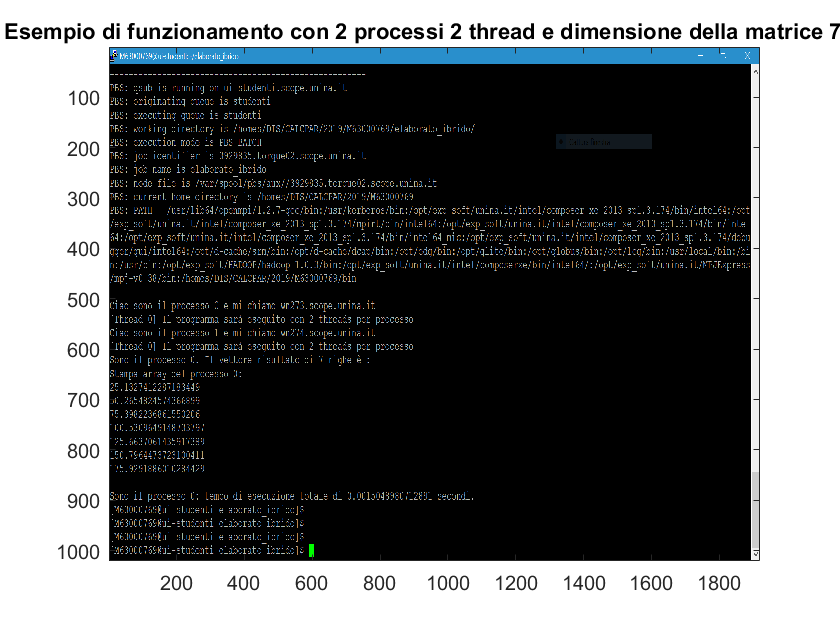

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

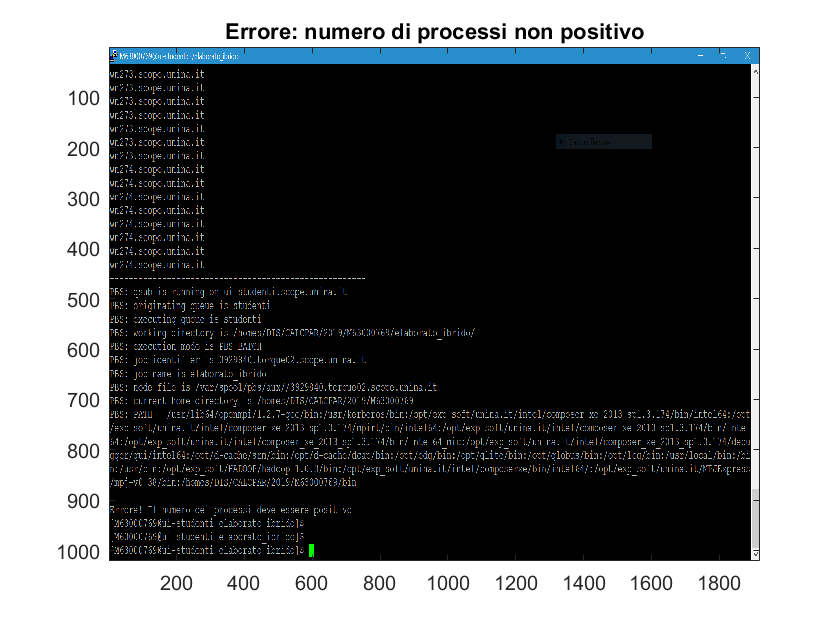

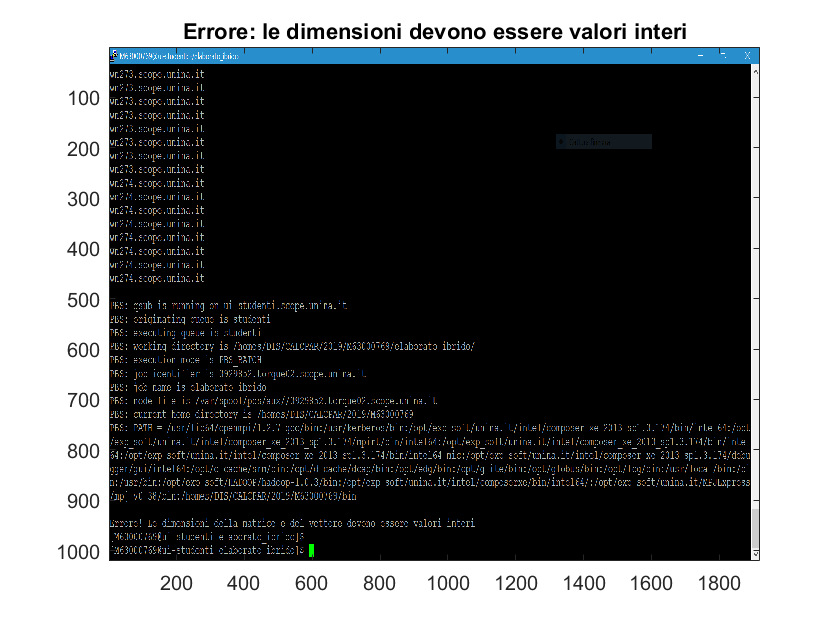

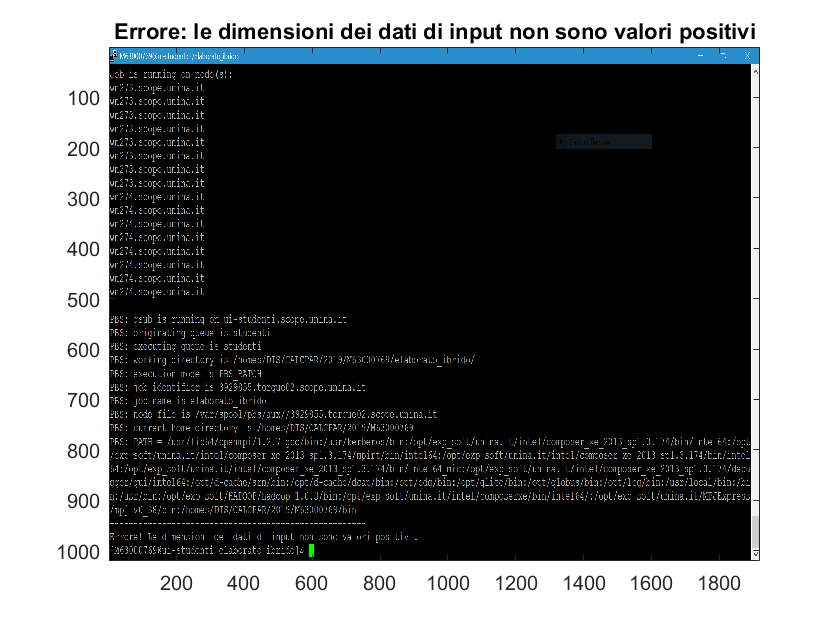

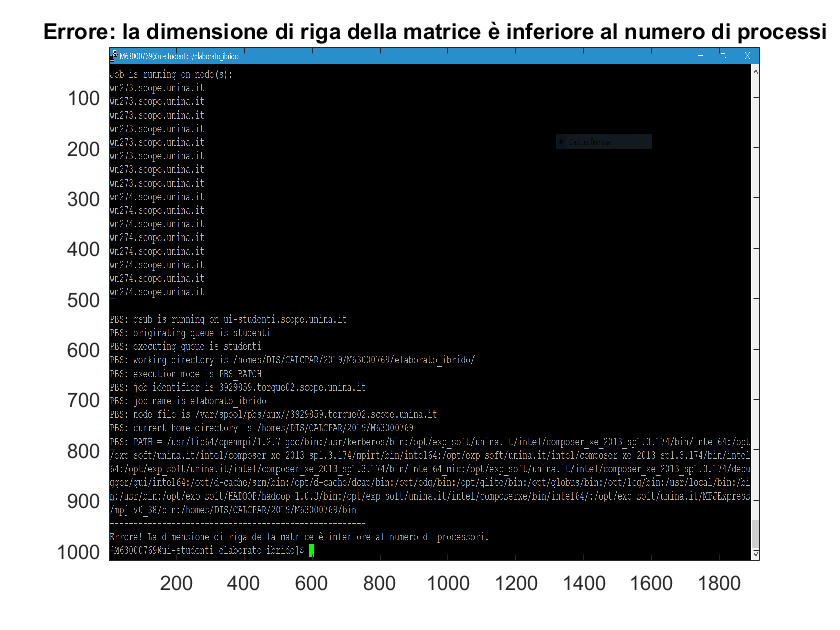

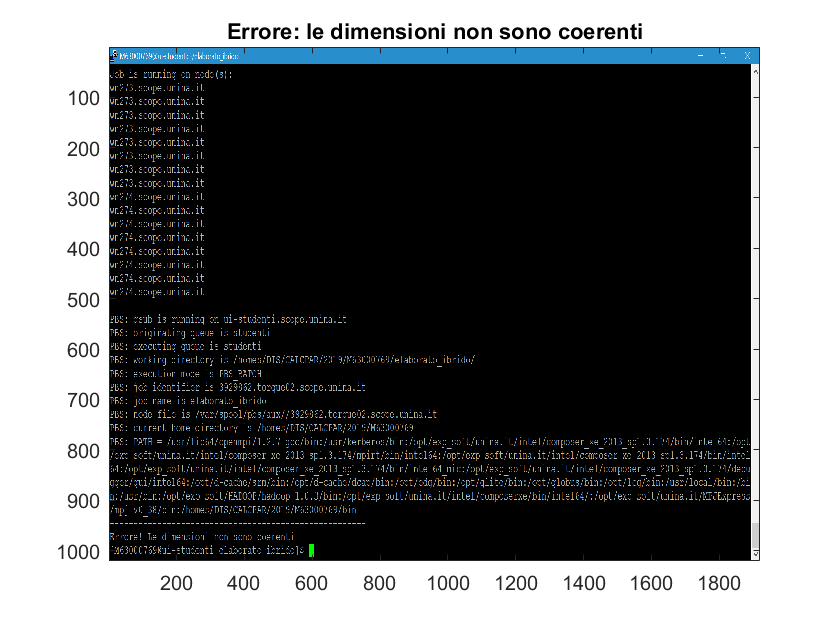

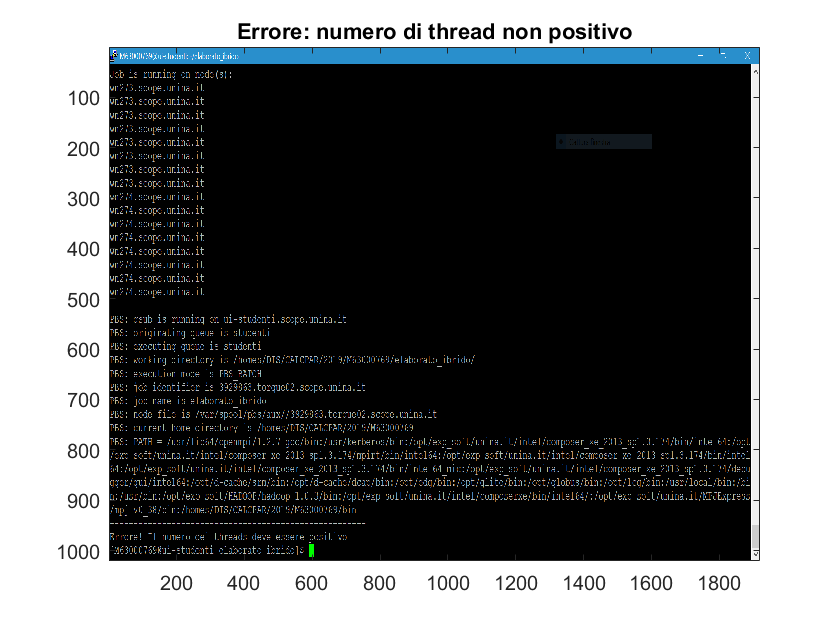

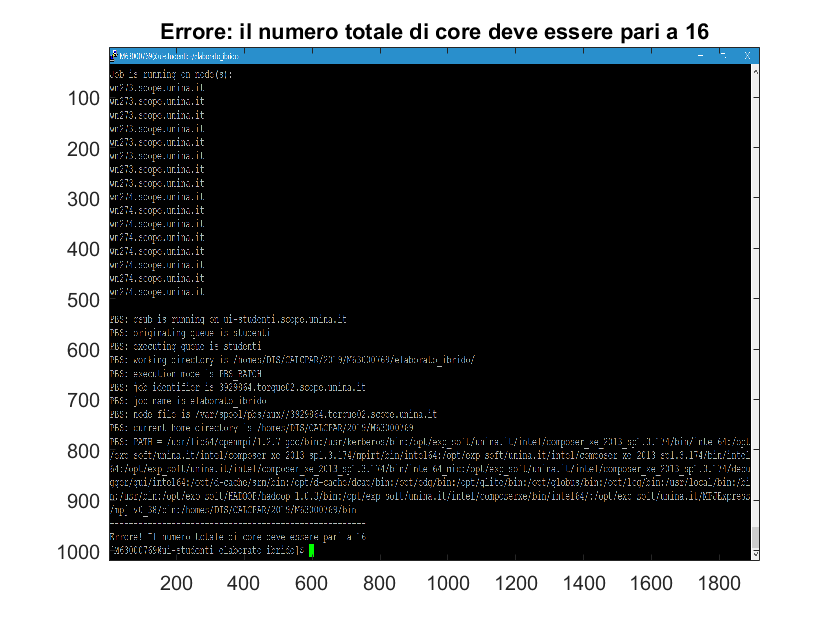

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE DIVERSE CONFIGURAZIONI 

Lo scopo di questo elaborato è individuare la migliore configurazione del numero di processi e thread: supponiamo che nel nostro caso l'architettura sia composta da 2 nodi MPI ciascuno formato da 2 cpu-socket di 4 core (pertanto si ha a disposizione un totale di 16 core) e si cerca di trovare la configurazione migliore per risolvere il prodotto matrice vettore su una matrice di dimensione 20000*15000.

A differenza degli elaborati precedenti, lo scopo non è quindi quello di studiare la scalabilità del problema (analizzare le caratteristiche dell'algoritmo quali efficienza, speedup ecc al variare della dimensione del problema e del numero di processi), ma quello di trovare la configurazione ottimale una volta fissate la dimensione del problema ed il numero di processi e thread.

Per configurazione ottimale si intende quella che minimizza l'overhead dovuto alle comunicazioni MPI e quello di gestione dei thread OpenMP rispetto al tempo di calcolo parallelo.

Le quattro alternative, con il numero di nodi fissato a 2, che abbiamo scelto di considerare sono:

- 16 processi single-thread;

- 8 processi con 2 thread;

- 4 processi con 4 thread;

- 2 processi con 8 thread.

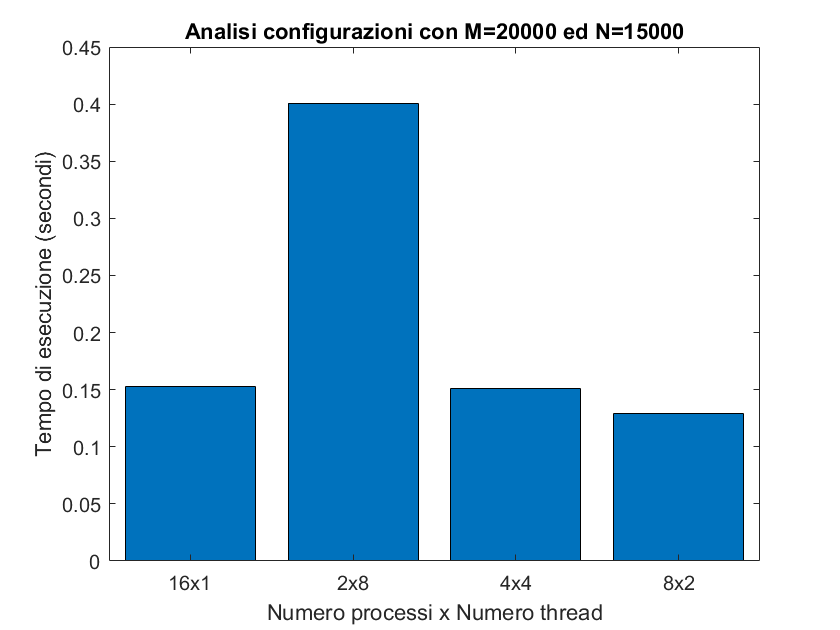

%script per il grafico
prestazioni

Analizzando l'istogramma ottenuto la configurazione che ha i tempi peggiori è quella composta da 2 processi con 8 thread mentre la migliore è quella composta da 8 processi con 2 thread. Le altre due configurazioni ottengono risultati intermedi.

Una possibile spiegazione del risultato è che, essendo la matrice distribuita per righe, conviene sfruttare al massimo la divisione per righe (e cioè il numero di processi) con un numero limitato di thread per non far pesare troppo l'overhead di creazione e gestione dei thread.

## ANALISI DELL' ACCURATEZZA

Confrontando il risultato ottenuto sul cluster Scope e quello ottenuto su MATLAB si ottiene il seguente errore relativo (tramite il comando `norm)`, fissando a 2 il numero di processi con 2 thread con dimensione della matrice pari a 7x8.

%esecuzione script per i test di accuratezza
accuratezza

risultato_scope = 	1.0e+02 *

   0.251327412287183
   0.502654824574366
   0.753982236861550
   1.005309649148730
   1.256637061435910
   1.507964473723100
   1.759291886010280


risultato_matlab = 	1.0e+02 *

   0.251327412287183
   0.502654824574367
   0.753982236861550
   1.005309649148734
   1.256637061435917
   1.507964473723100
   1.759291886010284


errore_relativo =      3.210969507161735e-15
